# **The evidence of social inequality on flooding duration at province scale in China**

## 1. 省尺度数据：

### 1.1 省对应内涝事件的duration

#### **1.1.1 数据源**：EM-DAT

链接：[Public EM-DAT platform (emdat.be)](https://public.emdat.be/data)

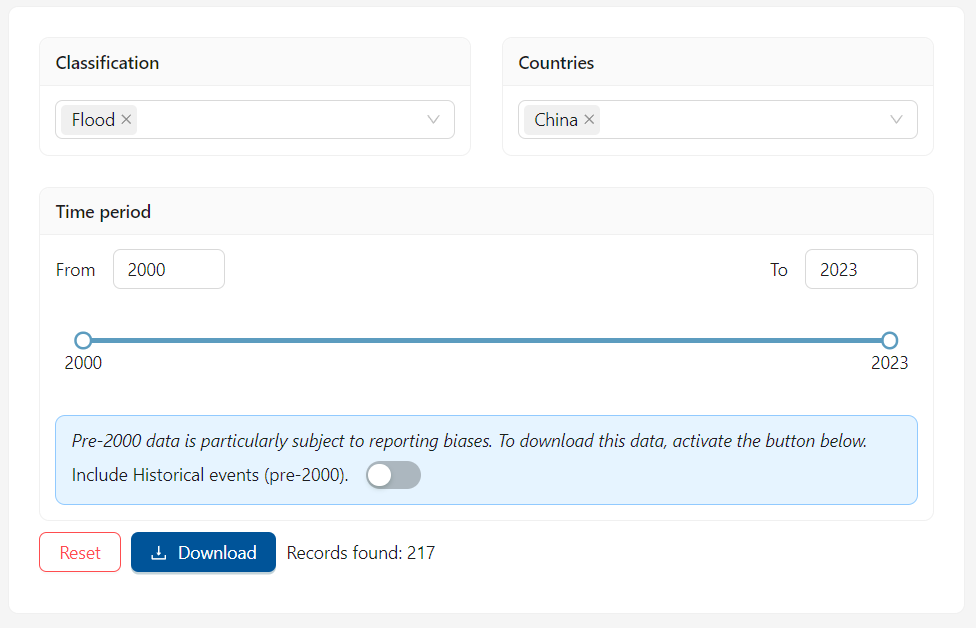

**下载文件**："E:\code\Py_workplace\satellite_flooding\Data\EM-DAT\public_emdat_custom_request_2023-12-24_8253b678-5268-4d3b-aeeb-2ca0abad5031.xlsx"

**缺陷**：省和更小行政级别数据难以对齐

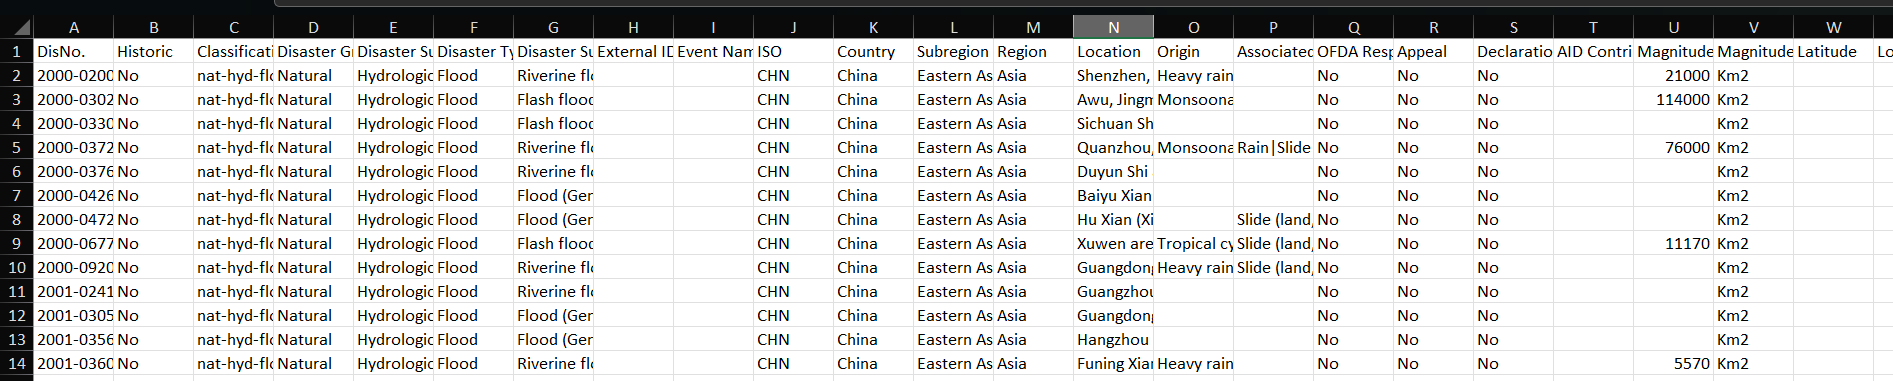

#### **1.1.2 将灾害数据匹配到行政单元**

方法1：[GDIS, a global dataset of geocoded disaster locations | Scientific Data (nature.com)](https://www.nature.com/articles/s41597-021-00846-6#Sec3)。该数据集发布了灾害所对应的位置。

下载：[Downloads » Geocoded Disasters (GDIS) Dataset, v1: Natural Disasters | SEDAC (columbia.edu)](https://sedac.ciesin.columbia.edu/data/set/pend-gdis-1960-2018/data-download#openModal)

方法2：EM-DAT数据中包含Admin-Units字段

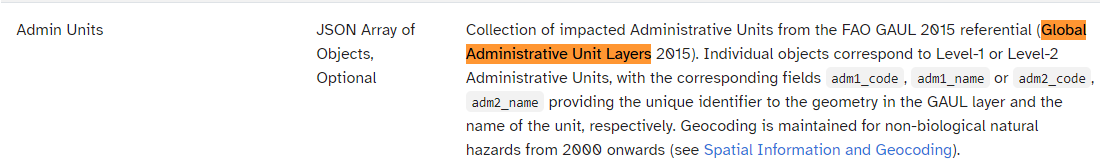

准备数据的思路：18年之前的，使用GDIS中的位置信息。18年之后的，使用原始EM-DAT数据，结合地图进行地理信息更新。

更新后的表格：EM-DAT-China_flood_with_geo.xlsx

### 1.2 省的经济发展指标：

数据源：国家统计局

## 2 分析1：散点图+线性回归

匹配经济发展指标到事件：事件发生年份受影响省份的经济指标

不考虑duration为1的事件。

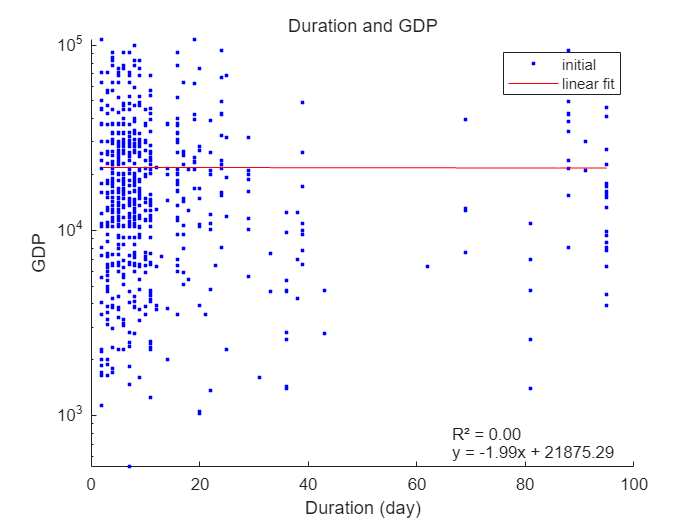

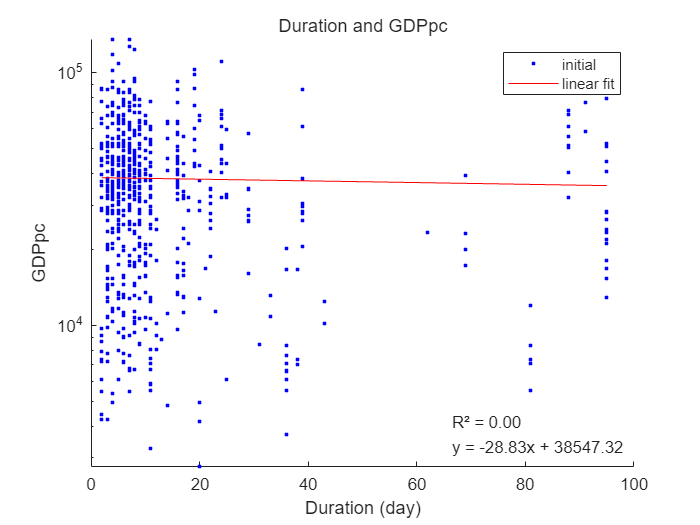

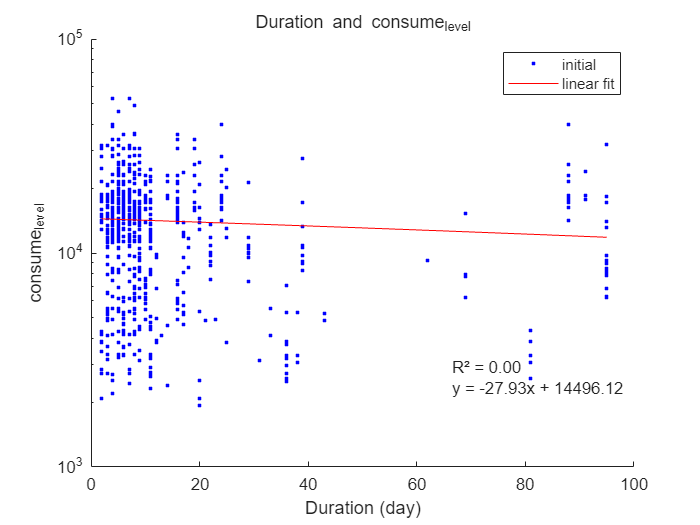

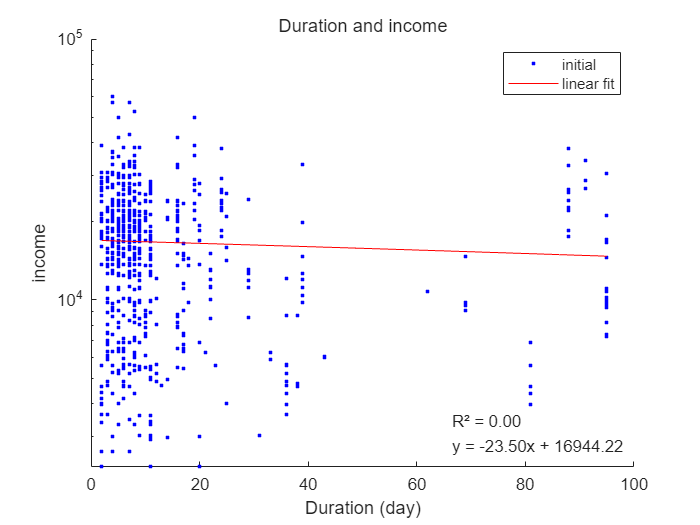

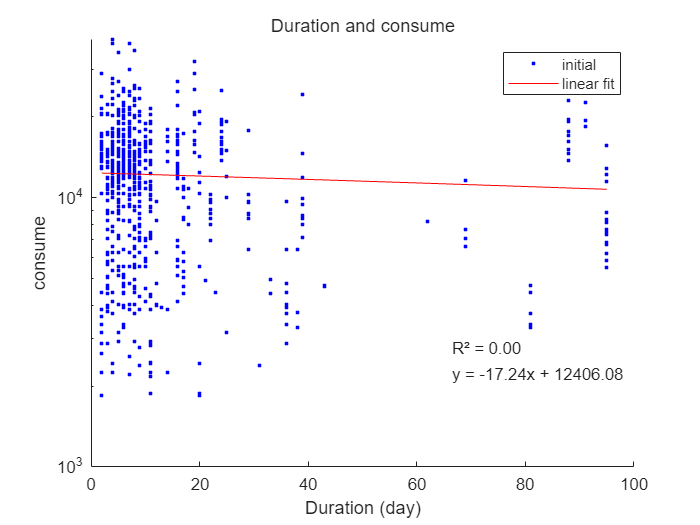

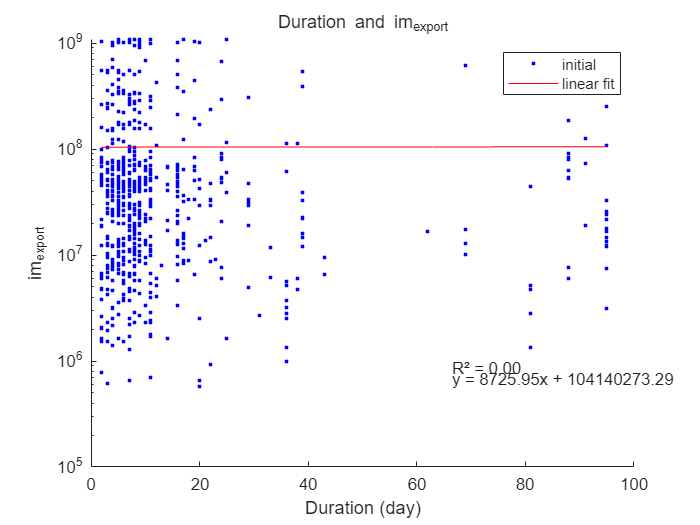

% 假设 data 是一个包含经济指标和灾害持续时间的表格
% 列名分别为：'DisasterDuration', 'GDP', 'GDPpc', 'ConsumeLevel', 'Income', 'Consume', 'ImExport'

% 过滤掉灾害持续时间为1天的行
filtered_data = EM_DAT_Duration(EM_DAT_Duration.DisasterDuration > 1, :);
filtered_data = filtered_data(filtered_data.GDP>0, :);


economicIndicators = {'GDP', 'GDPpc', 'consume_level', 'income', 'consume', 'im_export'};
nIndicators = length(economicIndicators);

for i = 1:nIndicators
    % 绘制散点图
    figure;
    % scatter(filtered_data.DisasterDuration, filtered_data.(economicIndicators{i}));
    
    % 将 y 轴设置为对数坐标系
    set(gca, 'YScale', 'log');
    
    % 线性拟合并绘制拟合线
    [fitResults, gof] = fit(filtered_data.DisasterDuration, filtered_data.(economicIndicators{i}), 'poly1');
    hold on;
    % plot(fitResults, filtered_data.(economicIndicators{i}));
    plot(fitResults, filtered_data.DisasterDuration, filtered_data.(economicIndicators{i}));

    legend('initial', 'linear fit');
    
    % 将拟合方程和 R² 值添加到图中
    fitEqn = sprintf('y = %.2fx + %.2f', fitResults.p1, fitResults.p2);
    fitInfo = sprintf('R² = %.2f', gof.rsquare);
    text(max(filtered_data.DisasterDuration)*0.7, min(filtered_data.(economicIndicators{i}))*1.2, fitEqn);
    text(max(filtered_data.DisasterDuration)*0.7, min(filtered_data.(economicIndicators{i}))*1.5, fitInfo);
    
    hold off;

    xlabel('Duration (day)');
    ylabel(economicIndicators{i});
    title(['Duration and ' economicIndicators{i}]);
end